# ENG432 Major Design Project

Samuel Brown 619710

Noah West 620683

Question 6) Controller Pole Placement

clear;
clc;

% Define reference values
Href = 60;  % From 9144m + Href
Mref = 0.6*343 - 182;         % Mach number

% Augment the system to include height h and mach number m
x6 = {'u', 'w', 'q', 'theta', 'h'};
y6 = {'mach number', 'height'};

load("matlabData.mat"); % Loading predefined system
A = [sys_mimo11.A, zeros(4,1); 0, 1, 0, 0, 0];
B = [sys_mimo11.B; zeros(1,2)];
C = [1 0 0 0 0; 0 0 0 0 1];

% New augmented MIMO system with added state variable height
sys_mimo6 = ss(A,B,C,zeros(2,2),'statename',x6,...
'inputname',sys_mimo11.InputName',...
'outputname',y6);

% Check controllability and observability
Co = ctrb(A, B);
Ob = obsv(A, C);

if (rank(Co) == min([size(A)]))
    disp("System is fully controllable");
else
    error("System is not fully controllable");
end

System is fully controllable


if (rank(Ob) == min([size(A)]))
    disp("System is fully observable");
else
    error("System is not fully observable");
end

System is fully observable


s = tf('s');

% Lag Times
tMM = .05; % Mach meter time constant
tTS = 5; % Thrust engine servo lag time
tES = .02; % Elevator servo time constant
tA = .8; % Altimeter time constant

% Input 1 lag: .2 / (s+.2) AKA Elevator servo
A1 = -1/tTS; B1 = 1; C1 = 1/tTS; D1 = 0;
G1 = ss(A1, B1, C1, D1);

% Input 2 lag: 50 / (s+50) AKA Thrust servo
A2 = -1/tES; B2 = 1; C2 = 1/tES; D2 = 0;
G2 = ss(A2, B2, C2, D2);

% Combine into diagonal (MIMO) system
G1.StateName = {'lag_mach'};
G2.StateName = {'lag_height'};
lag_block = blkdiag(G1, G2);

sys_control_forward = series(1, lag_block);
sys_forward = series(sys_control_forward, sys_mimo6);


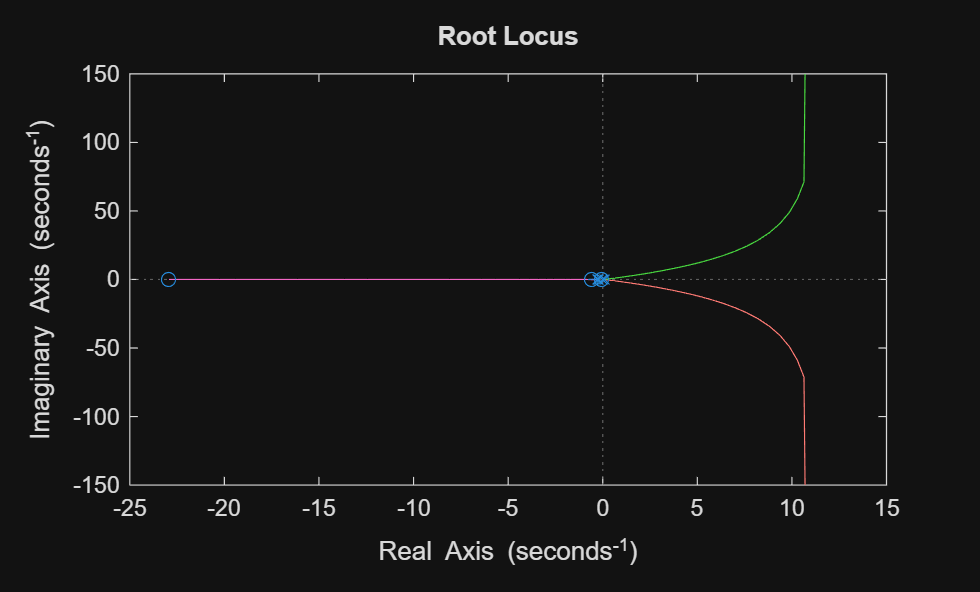

rlocus(sys_forward(1,1))

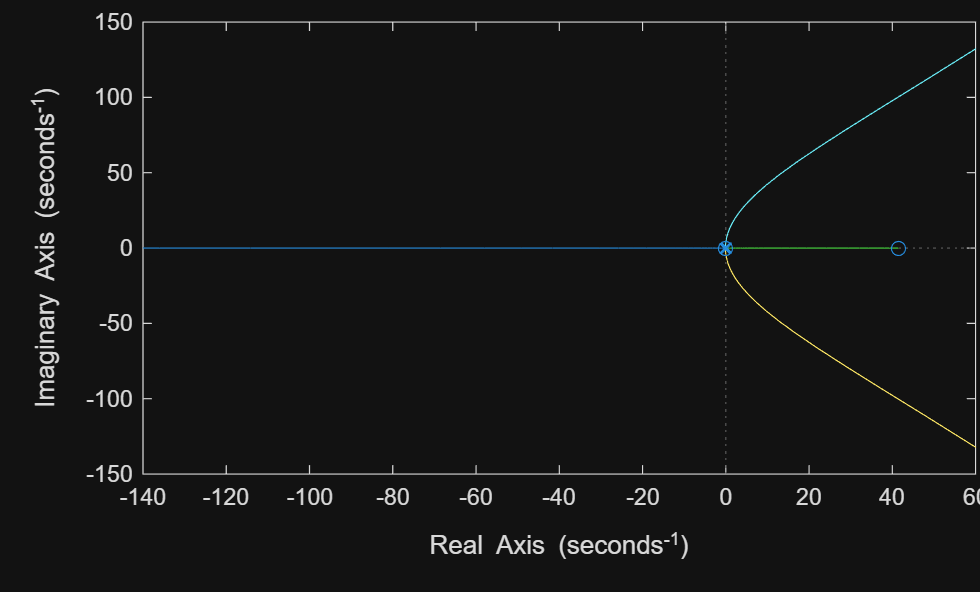

rlocus(sys_forward(2,1))

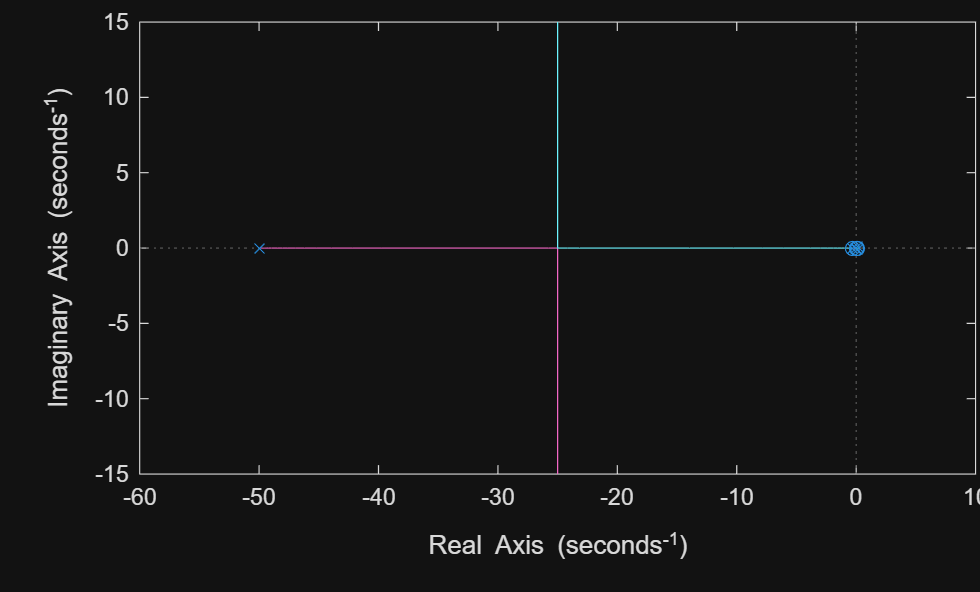

rlocus(sys_forward(1,2))

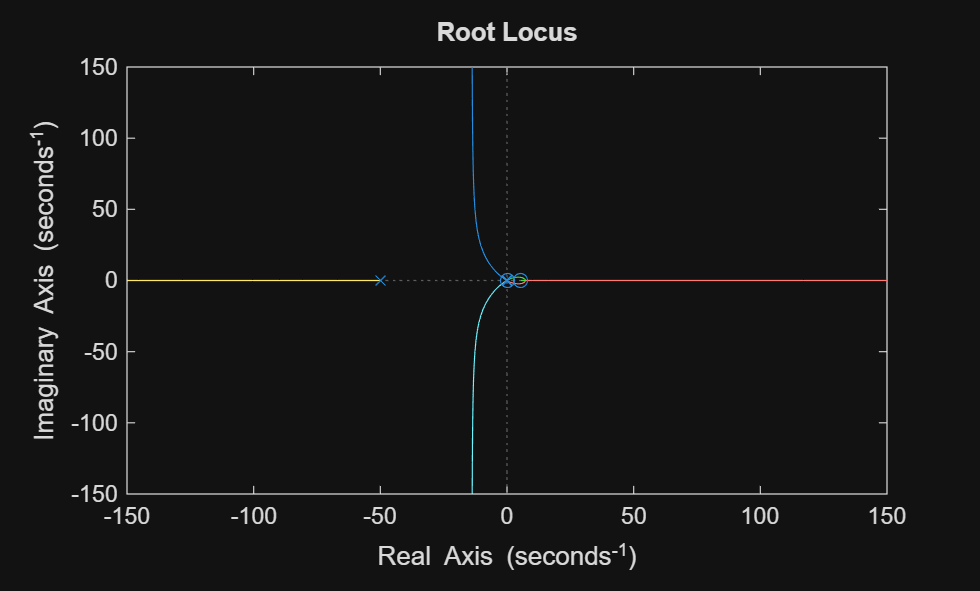

rlocus(sys_forward(2,2))

% Feedback lag 1: H(s) = 20 / (s + 20)
A_f1 = -1/tMM; B_f1 = 1; C_f1 = 1/tMM; D_f1 = 0;
H1= ss(A_f1, B_f1, C_f1, D_f1);  

% Feedback lag 2: H(s) = 1.25 / (s + 1.25)
A_f2 = -1/tA; B_f2 = 1; C_f2 = 1/tA; D_f2 = 0;
H2= ss(A_f2, B_f2, C_f2, D_f2);

H1.StateName = {'y_mach'};
H2.StateName = {'y_height'};
H_mimo = blkdiag(H1, H2);  % 2x2 MIMO if there are two outputs fed back

sys_cl = feedback(sys_forward, H_mimo);  % Negative feedback: u = r - H(s)*y
sys_cl.InputName = {'Mref', 'Href'};


% Servomechanism
n = size(sys_cl.A,1);
m = size(sys_cl.B,2);

A_sm = [sys_cl.A, zeros(n,m); -sys_cl.C, zeros(m)];
B_sm = [sys_cl.B; zeros(m)];
C_sm = [sys_cl.C, zeros(m)];
sys_sm = ss(A_sm,B_sm,C_sm,sys_cl.D);

% Get controllable states
tol = 1e-8;
[Ab_cl,Bb_cl,Cb_cl,T,k] = ctrbf(sys_sm.A, sys_sm.B, sys_sm.C, tol);
sum(k)

ans = 11


Ac_cl = Ab_cl(end-sum(k)+1:end, end-sum(k)+1:end);
Bc_cl = Bb_cl(end-sum(k)+1:end, :);
Cc_cl = Cb_cl(:, end-sum(k)+1:end);

p = size(Ab_cl,1);

% Target poles
% Short period pole locations
sigma_d_sp = -20;
zeta_sp = 0.8; % 0.35 <= zeta_sp <= 1.3
theta_sp = acosd(zeta_sp);
omega_d_sp = tand(theta_sp)*-sigma_d_sp;
sp = 1/((s - (sigma_d_sp+1j*omega_d_sp))*(s - (sigma_d_sp-1j*omega_d_sp)));

% Phugoid pole locations
sigma_d_ph = -0.1;
zeta_ph = 0.04; % zeta_ph = 0.04
theta_ph = acosd(zeta_ph);
omega_d_ph = tand(theta_ph)*-sigma_d_ph;
ph = 1/((s - (sigma_d_ph+1j*omega_d_ph))*(s - (sigma_d_ph-1j*omega_d_ph)));

% Actuator pole locations
sE = 1/(s+50);
sT = 1/(s+.2);

% Meter pole locations
mM = 1/(s+20);
mA = 1/(s+1.25);

% Servomechanism
svM = 1/(s+0.03); % Servo for mach
svH = 1/(s+0.02); % Servo for height

% Spare
sSp = 1/(s+60);

p_cl = pole(sp*ph*sT*sE*mM*mA*svM*svH*sSp);
[gains, prec] = place(Ac_cl, Bc_cl, p_cl);
K_cl = [zeros(m,p-sum(k)), gains] * T; % Find gains to place poles
Kx = K_cl(:, 1:n);
Ke = -K_cl(:, n+1:end);

% Form final system
% Form final system with state feedback and servomechanism
sys_final = ss([sys_cl.A - sys_cl.B*Kx, sys_cl.B*Ke; -sys_cl.C, zeros(m)],...
    [zeros(n,m); eye(m)], [sys_cl.C, zeros(m)], sys_cl.D);

% Display system
tol = 1e-3;
output = zpk(minreal(zpk(tf(sys_final)),tol))


output =
 
  From input 1 to output...
       -791.76 (s+62.23) (s+29.04) (s+0.02995) (s-0.004743) (s^2 + 0.1446s + 6.916)
   1:  -----------------------------------------------------------------------------
       (s+60) (s+50) (s+0.2) (s+0.03) (s+0.02) (s^2 + 0.2s + 6.25) (s^2 + 40s + 625)
 
                   305.59 s (s+52.56) (s+19.97) (s-41.41) (s+1.041) (s+0.03665)
   2:  ------------------------------------------------------------------------------------
       (s+60) (s+50) (s+20) (s+0.2) (s+0.03) (s+0.02) (s^2 + 0.2s + 6.25) (s^2 + 40s + 625)
 
  From input 2 to output...
              -20.699 s (s+59.8) (s+16.33) (s+1.483) (s+0.04912) (s^2 + 3.79s + 5.632)
   1:  --------------------------------------------------------------------------------------
       (s+60) (s+50) (s+1.25) (s+0.2) (s+0.03) (s+0.02) (s^2 + 0.2s + 6.25) (s^2 + 40s + 625)
 
                -1.055 (s+117.6) (s+66.72) (s-41.57) (s+0.2031) (s+0.02011)
   2:  --------------------------------------------------

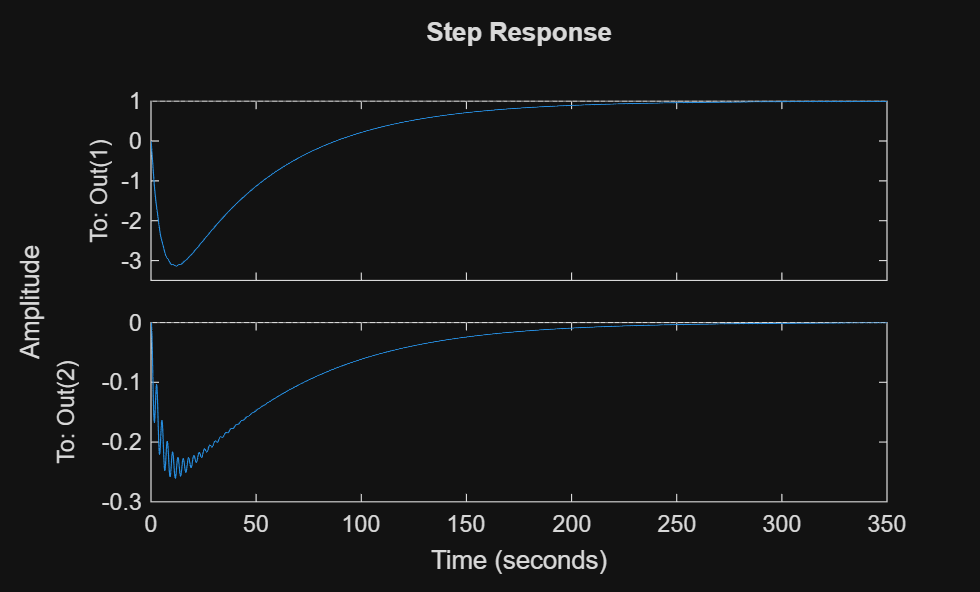

step(output(:,1))

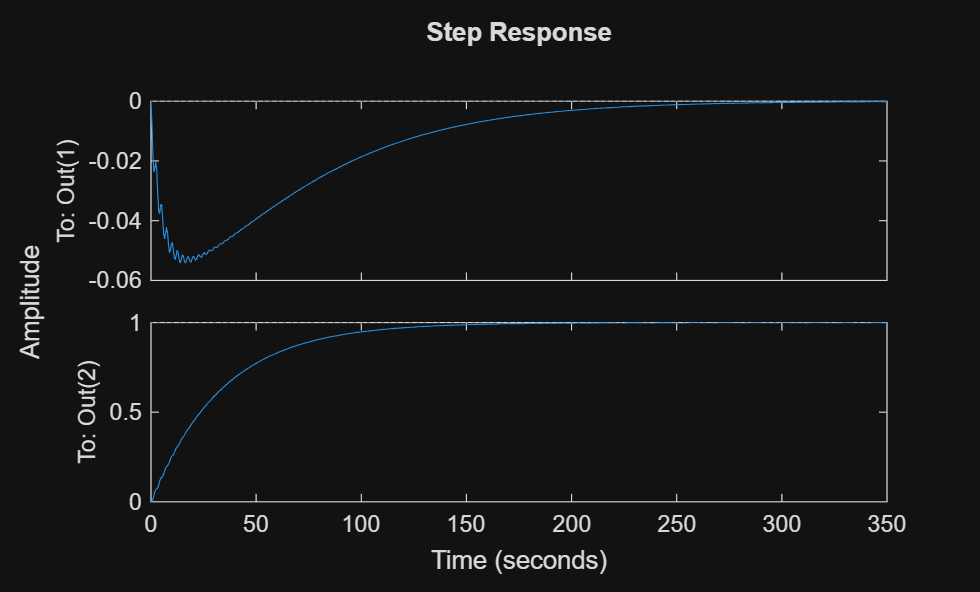

step(output(:,2))

dcgain(zpk(minreal(zpk(tf(sys_final)),tol)))

ans =     0.9996    0.0000
   -0.0000    0.9995


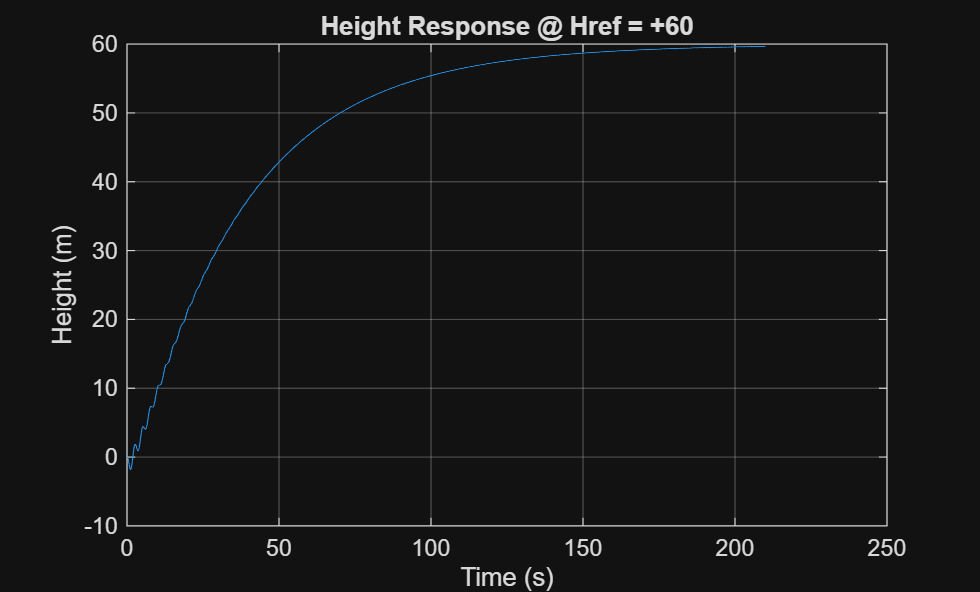


% Create RespConfig objects for step amplitudes
optM = RespConfig;
optM.Amplitude = Mref;  % Step amplitude for Mach number reference

optH = RespConfig;
optH.Amplitude = Href;  % Step amplitude for height reference
t1 = 0:0.1:300;
t2 = 0:0.1:210;

figure;
plot(t2, step(output(2,2), t2, optH)+ step(output(2,1), t2, optM))
title('Height Response @ Href = +60')
ylabel('Height (m)');
xlabel('Time (s)'); grid on;

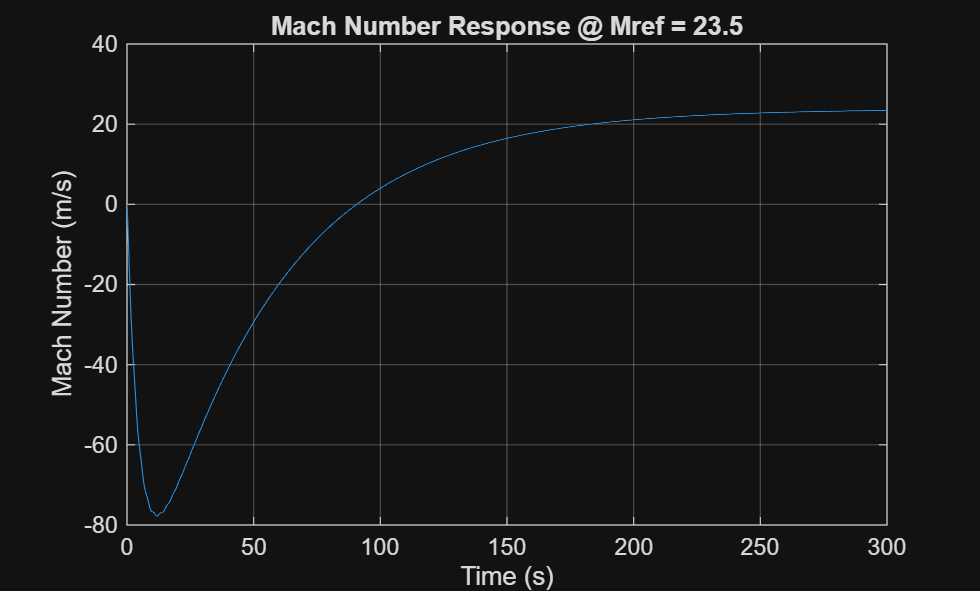


figure;
plot(t1, step(output(1,1), t1, optM)+ step(output(1,2), t1, optH))
title('Mach Number Response @ Mref = 23.5')
ylabel('Mach Number (m/s)');
xlabel('Time (s)'); grid on;